# Replace Table Placeholder with Table

Add a `Title and Table` slide to a presentation and then replace the title and table placeholders with your own title and table.

Import the PPT package so that you do not have to use long, fully qualified names for the PPT API classes.

import mlreportgen.ppt.*

Create a presentation.

ppt = Presentation("myTablePlaceholderPresentation.pptx");
open(ppt);

Add a slide that has a `Title and Table` layout.

slide = add(ppt,"Title and Table");

Use the `find` method of the slide object to find the placeholder object that has the name `Title`.

titlePlaceholderObj = find(slide,"Title")

The `find` method returns an `mlreportgen.ppt.TextBoxPlaceholder` object.

Replace the placeholder content with the title text.

replace(titlePlaceholderObj,"Fourth-Order Magic Square");

Use the `find` method of the slide object to find the placeholder object that has the name `Table`.

tablePlaceholderObj = find(slide,"Table")

The `find` method returns an `mlreportgen.ppt.TablePlaceholder` object.

Replace the table placeholder with a table for a fourth-order magic square.

replace(tablePlaceholderObj,Table(magic(4)));

Close and view the presentation

close(ppt);
rptview(ppt);

Here is the slide in the generated presentation:

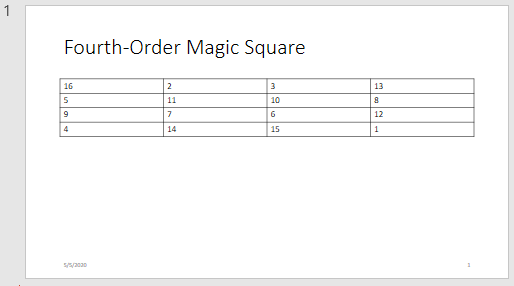

*Copyright 2020 The MathWorks, Inc.*